# 创建和训练深度学习模型

该脚本可创建和训练具有以下属性的深度学习网络:

运行此脚本以创建网络层、导入训练和验证数据并训练网络。网络层存储在工作区变量 `layers` 中。经过训练的网络存储在工作区变量 `net` 中。

要了解详细信息，请参阅 [从深度网络设计器生成 MATLAB 代码](matlab:helpview('deeplearning','generate_matlab_code'))。

由 MATLAB 于 2024-11-16 19:52:43 自动生成

## 导入数据

导入训练和验证数据。

digitDatasetPath = fullfile('E:','Matlab2023/数字图像处理课程设计/training2/');
 
imds = imageDatastore(digitDatasetPath, ...
    'IncludeSubfolders',true, ...
    'LabelSource','foldernames');

numTrainFiles = 150;
[imdsTrain,imdsValidation] = splitEachLabel(imds,numTrainFiles,'randomize');

## 设置训练选项

指定训练时要使用的选项。

options = trainingOptions('sgdm', ...
    'MaxEpochs',8, ...
    'ValidationData',imdsValidation, ...
    'ValidationFrequency',30, ...
    'Verbose',false, ...
    'Plots','training-progress');

## 创建层组

inputSize = [32 32 1];
numClasses = 10;
 
layers = [
    imageInputLayer(inputSize)
    convolution2dLayer(5,20)
    batchNormalizationLayer
    reluLayer
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer];

## 训练网络

使用指定的选项和训练数据对网络进行训练。

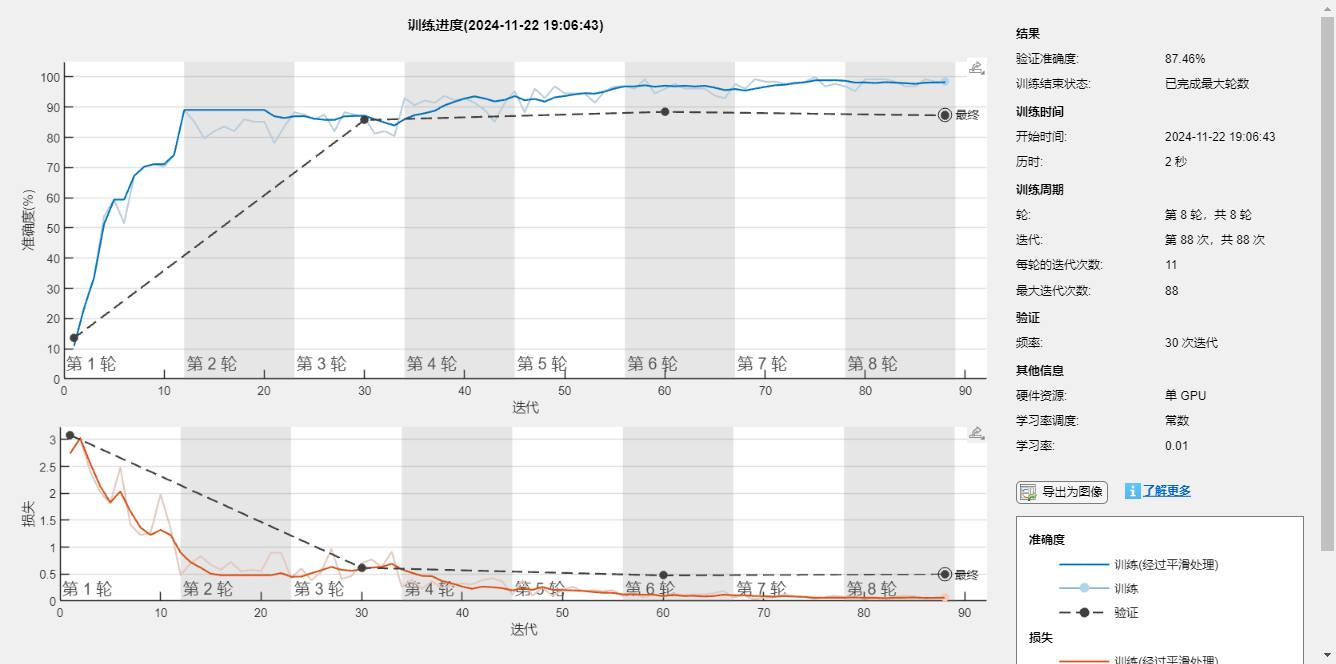

net = trainNetwork(imdsTrain,layers,options);


YPred = classify(net,imdsValidation);
YValidation = imdsValidation.Labels;
accuracy = mean(YPred == YValidation);
save('trainedNet.mat', 'net');